# Lab 8 - Pseudo-experiment data analysis

Thomas Conaway

Lab Partners: Avi Soval, Jeff Jiang

Time: 6 hours

Requires knowing how to do Lab 7 to proceed.

clc; clear; close all;
% h5disp("data_lowLumi_pt_1000_1200.h5");
% h5disp("data_highLumi_pt_1000_1200.h5");
highitems = h5read("data_highLumi_pt_1000_1200.h5",'/data/block0_items');
highvalues = h5read("data_highLumi_pt_1000_1200.h5",'/data/block0_values');
lowitems = h5read("data_lowLumi_pt_1000_1200.h5",'/data/block0_items');
lowvalues = h5read("data_lowLumi_pt_1000_1200.h5",'/data/block0_values');
signal = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
bg = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');
% expected yields the same, nhiggs = 50 and nqcd = 2000

## Problem 1 - High luminosity data

Quick test plot with mass:

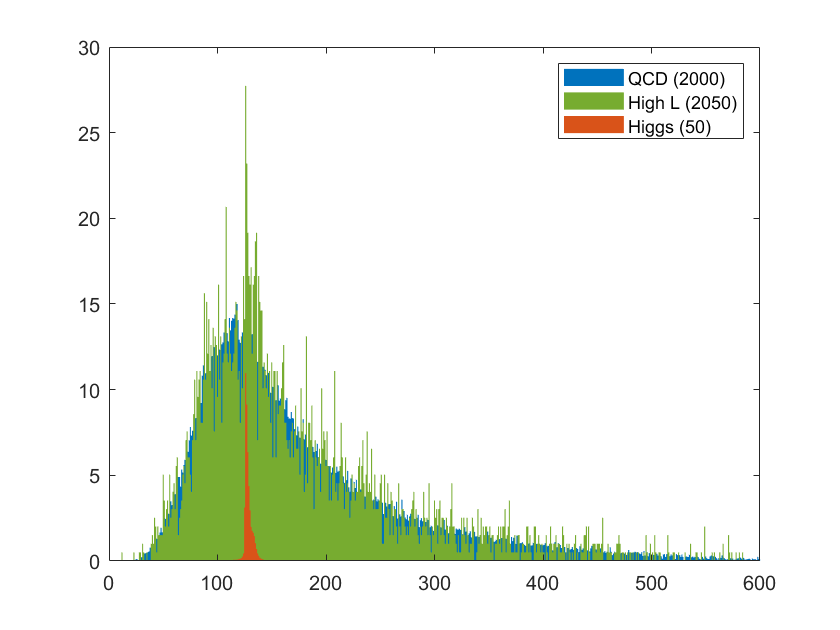

close all hidden;
x = 0:1:800;
h = histogram(signal(4,:),x,"Normalization","pdf","EdgeColor","none",'HandleVisibility','off');
hold on;
set(h,"Visible","off");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * 50;
h2 = histogram(bg(4,:),x,"Normalization","pdf","EdgeColor","none",'HandleVisibility','off');
set(h2,"Visible","off");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * 2000;
h3 = histogram(highvalues(4,:),x,"Normalization","pdf","EdgeColor","none",'HandleVisibility','off');
set(h3,"Visible","off");
h3.BinCounts = h3.BinCounts/sum(h3.BinCounts) * 2050;
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#0072BD');
bar(h3.BinEdges(2:end),h3.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#77AC30');
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#D95319');
legend("QCD (" + sum(h2.BinCounts) + ")","High L (2050)","Higgs (50)");
xlim([0,600]);
hold off;

The High L distribution has a very sharp peak at 125, looking much like the sum of the expected Higgs and QCD (should be easier to see with a true stacked histogram rather than a layered one).

Plots with no event selection:

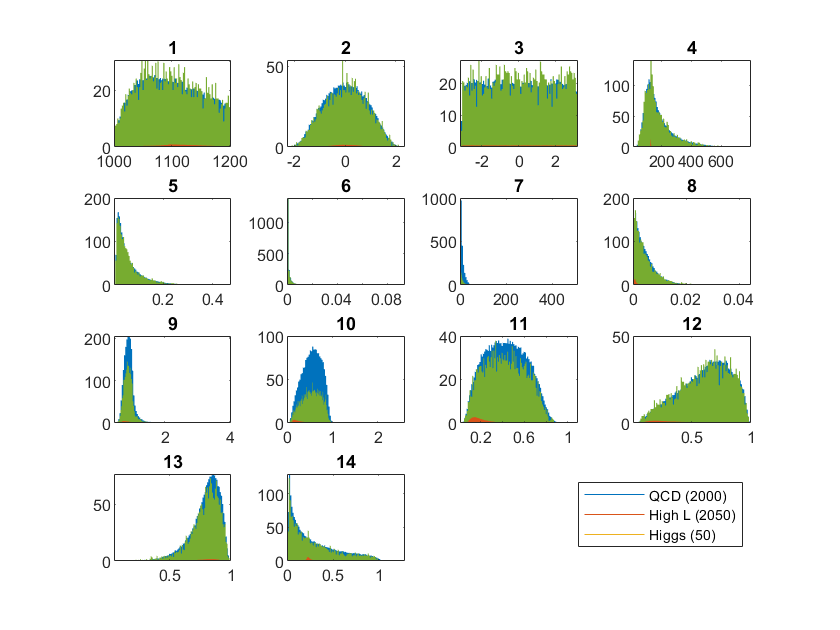

close all hidden;
% x = 0:1:800;
for k = 1:14
    subplot(4,4,k);
    h = histogram(signal(k,:),100,"Normalization","pdf",'HandleVisibility','off');
    set(h,'Visible','off');
    h.BinCounts = h.BinCounts/sum(h.BinCounts) * 50;
    hold on;
    h2 = histogram(bg(k,:),100,"Normalization","pdf",'HandleVisibility','off');
    set(h2,'Visible','off');
    h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * 2000;
    h3 = histogram(highvalues(k,:),100,"Normalization","pdf",'HandleVisibility','off');
    set(h3,'Visible','off');
    h3.BinCounts = h3.BinCounts/sum(h3.BinCounts) * 2050;
    b2 = bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#0072BD');
    b3 = bar(h3.BinEdges(2:end),h3.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#77AC30');
    b = bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#D95319');
    title("" + k);
    hold off;
end
subplot(4,4,16);
plot(0,0,  0,0,  0,0,  0,0);
axis off;
legend('QCD (2000)','High L (2050)','Higgs (50)');

Plots with event selection:

lowercut = 124;
uppercut = 136;
lowercut7 = 0;
uppercut7 = 4;
lowercut14 = 0.2;
uppercut14 = 100;
%
masssignal = signal(4,:);
massbg = bg(4,:);
masshighvalues = highvalues(4,:);

% cutsignal = masssignal(masssignal < uppercut);
% cutsignal = cutsignal(cutsignal > lowercut);
% cutbg = massbg(massbg < uppercut);
% cutbg = cutbg(cutbg > lowercut);
% cuthighvalues = masshighvalues(masshighvalues < uppercut);
% cuthighvalues = cuthighvalues(cuthighvalues > lowercut);
% 
% % cutsignal = cutsignal(cutsignal < uppercut7);
% % cutsignal = cutsignal(cutsignal > lowercut7);
% % cutbg = cutbg(cutbg < uppercut7);
% % cutbg = cutbg(cutbg > lowercut7);
% % cuthighvalues = cuthighvalues(cuthighvalues < uppercut7);
% % cuthighvalues = cuthighvalues(cuthighvalues > lowercut7);
% 
% nhiggs = numel(cutsignal)/numel(signal(4,:))*50;
% nqcd = numel(cutbg)/numel(bg(4,:))*2000;
% nhighl = numel(cuthighvalues)/numel(masshighvalues)*2050;
% nhiggs/sqrt(nqcd)
%
newcutsignal = signal;
newcutbg = bg;
newcuthighvalues = highvalues;
for k = 1:100000
    % mass (4)
    if newcutsignal(4,k) > uppercut || newcutsignal(4,k) < lowercut
        newcutsignal(:,k) = nan;
    end
    if newcutbg(4,k) > uppercut || newcutbg(4,k) < lowercut
        newcutbg(:,k) = nan;
    end
    % 2-3 ECF (7)
    if newcutsignal(7,k) > uppercut7 || newcutsignal(7,k) < lowercut7
        newcutsignal(:,k) = nan;
    end
    if newcutbg(7,k) > uppercut7 || newcutbg(7,k) < lowercut7
        newcutbg(:,k) = nan;
    end
    % KtDeltaR (14)
    if newcutbg(14,k) > uppercut14 || newcutbg(14,k) < lowercut14
        newcutbg(:,k) = nan;
    end
end
for k = 1:numel(newcuthighvalues(4,:))
    % mass (4)
    if newcuthighvalues(4,k) > uppercut || newcuthighvalues(4,k) < lowercut
        newcuthighvalues(:,k) = nan;
    end
    % 2-3 ECF (7)
    if newcuthighvalues(7,k) > uppercut7 || newcuthighvalues(7,k) < lowercut7
        newcuthighvalues(:,k) = nan;
    end
    % KtDeltaR (14)
    if newcuthighvalues(14,k) > uppercut14 || newcuthighvalues(14,k) < lowercut14
        newcuthighvalues(:,k) = nan;
    end
end
test1 = newcutsignal(4,:);
test2 = newcutbg(4,:);
test3 = newcuthighvalues(4,:);

numelsignal = length(test1(~isnan(test1)));
numelbg = length(test2(~isnan(test2)));
numelhighl = length(test3(~isnan(test3)));

nhiggs = numelsignal/numel(signal(4,:))*50;
nqcd = numelbg/numel(bg(4,:))*2000;
nhighl = numelhighl/numel(masshighvalues)*2050;

nhiggs/sqrt(nqcd)

ans = 15.0614

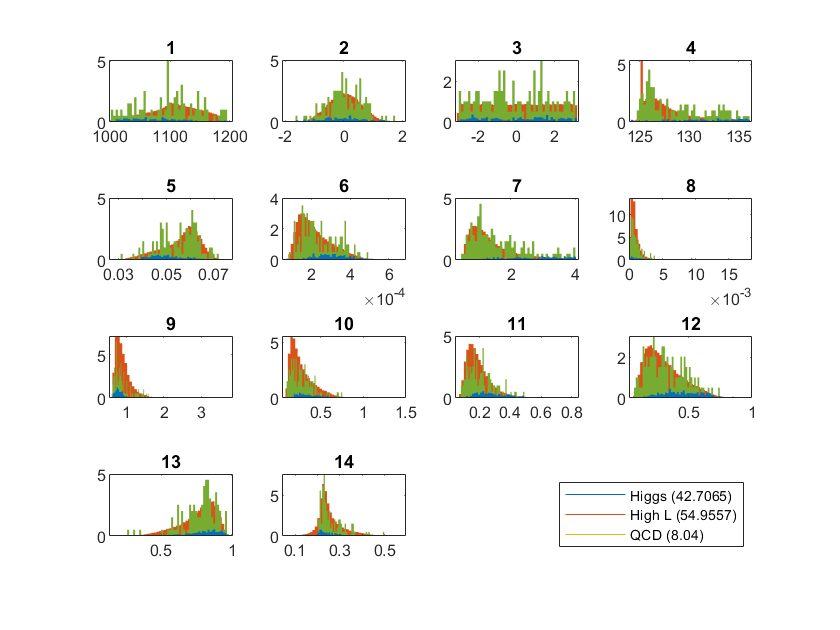

% plotting
close all hidden;
for k = 1:14
    loopsignal = newcutsignal(k,:);
    loopbg = newcutbg(k,:);
    loophighvalues = newcuthighvalues(k,:);
    subplot(4,4,k);
    h = histogram(loopsignal,50,"Normalization","pdf",'HandleVisibility','off');
    set(h,'Visible','off');
    h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
    hold on;
    h2 = histogram(loopbg,50,"Normalization","pdf",'HandleVisibility','off');
    set(h2,'Visible','off');
    h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;
    h3 = histogram(loophighvalues,50,"Normalization","pdf",'HandleVisibility','off');
    set(h3,'Visible','off');
    h3.BinCounts = h3.BinCounts/sum(h3.BinCounts) * nhighl;
    b = bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#D95319');    
    b3 = bar(h3.BinEdges(2:end),h3.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#77AC30');
    
    b2 = bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#0072BD');

    title("" + k);
    hold off;
end
subplot(4,4,16);
plot(0,0,  0,0,  0,0,  0,0);
axis off;
legend("Higgs (" + nhiggs + ")","High L (" + nhighl + ")","QCD (" + nqcd + ")");

After event selection, most of the background has been eliminated while preserving our Higgs sample. We also see that the high luminosity data follows our follows our expected Higgs distribution, now that it has the background filtered out of it.

Evaluating observed significance and comparing results to expectation:

nhiggs/sqrt(nqcd)

ans = 15.0614

nhiggs/sqrt(abs(nhighl-nhiggs)) % not sure how else to do it, should be lower than pure training nhiggs

ans = 12.2022

(nhighl-nqcd)/sqrt(nqcd) % probably shouldn't get higher

ans = 16.5459

(nhighl-nqcd)/sqrt(abs(nhighl-nhiggs)) % fancier, also lower

ans = 13.4049

## Problem 2 - Low luminosity data

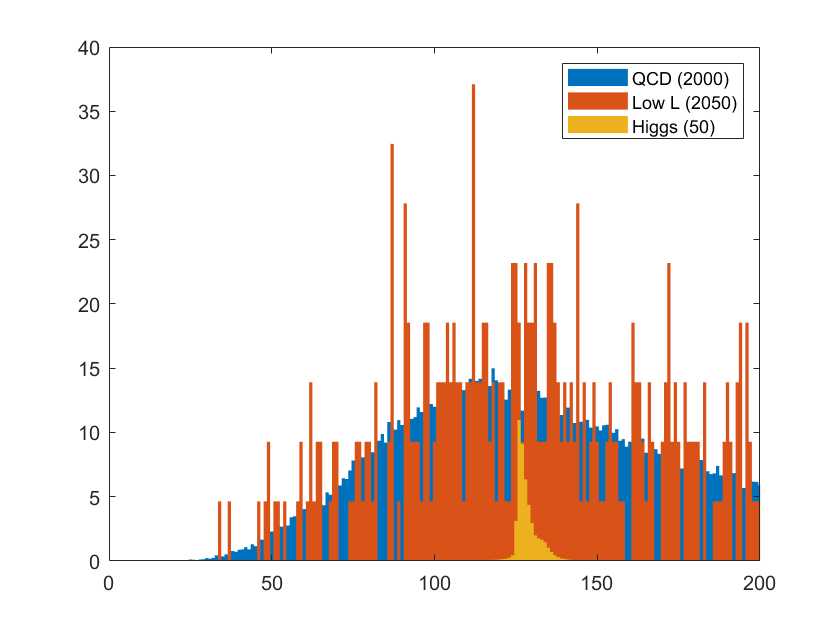

x = 0:1:800;
f1 = figure();
f2 = figure("Visible","off");
h = histogram(signal(4,:),x,"Normalization","pdf","EdgeColor","none");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * 50;
hold on;
h2 = histogram(bg(4,:),x,"Normalization","pdf","EdgeColor","none");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * 2000;
h3 = histogram(lowvalues(4,:),x,"Normalization","pdf","EdgeColor","none");
h3.BinCounts = h3.BinCounts/sum(h3.BinCounts) * 2050;
hold off;

figure(f1);
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
hold on;
bar(h3.BinEdges(2:end),h3.BinCounts,"Edgecolor","none","BarWidth",1);
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);
legend("QCD (" + sum(h2.BinCounts) + ")","Low L (2050)","Higgs (50)");
xlim([0,200]);
hold off;

Plots with no event selection:

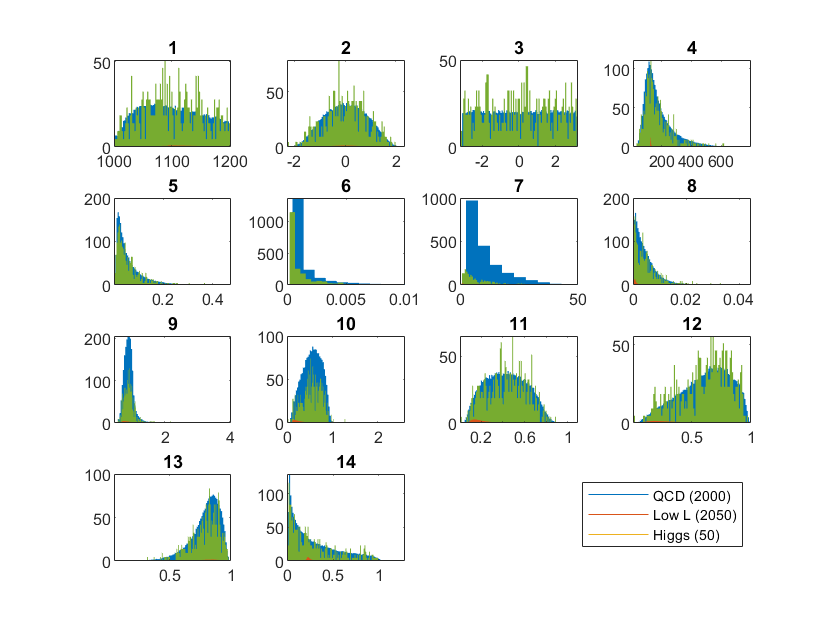

close all hidden;
% x = 0:1:800;
for k = 1:14
    subplot(4,4,k);
    h = histogram(signal(k,:),100,"Normalization","pdf",'HandleVisibility','off');
    set(h,'Visible','off');
    h.BinCounts = h.BinCounts/sum(h.BinCounts) * 50;
    hold on;
    h2 = histogram(bg(k,:),100,"Normalization","pdf",'HandleVisibility','off');
    set(h2,'Visible','off');
    h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * 2000;
    h3 = histogram(lowvalues(k,:),100,"Normalization","pdf",'HandleVisibility','off');
    set(h3,'Visible','off');
    h3.BinCounts = h3.BinCounts/sum(h3.BinCounts) * 2050;
    b2 = bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#0072BD');
    b3 = bar(h3.BinEdges(2:end),h3.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#77AC30');
    b = bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#D95319');
    title("" + k);
    if k == 6
        xlim([0,0.01]);
    end
    if k == 7
        xlim([0,50]);
    end
    hold off;
end
subplot(4,4,16);
plot(0,0,  0,0,  0,0,  0,0);
axis off;
legend('QCD (2000)','Low L (2050)','Higgs (50)');

Plots with event selection:

lowercut = 124;
uppercut = 136;
lowercut7 = 0;
uppercut7 = 4;
lowercut14 = 0.2;
uppercut14 = 100;
%
masssignal = signal(4,:);
massbg = bg(4,:);
masshighvalues = lowvalues(4,:); % rename
%
newcutsignal = signal;
newcutbg = bg;
newcuthighvalues = lowvalues; % newcuthighvalues should be renamed if there is time
for k = 1:100000
    % mass (4)
    if newcutsignal(4,k) > uppercut || newcutsignal(4,k) < lowercut
        newcutsignal(:,k) = nan;
    end
    if newcutbg(4,k) > uppercut || newcutbg(4,k) < lowercut
        newcutbg(:,k) = nan;
    end
    % 2-3 ECF (7)
    if newcutsignal(7,k) > uppercut7 || newcutsignal(7,k) < lowercut7
        newcutsignal(:,k) = nan;
    end
    if newcutbg(7,k) > uppercut7 || newcutbg(7,k) < lowercut7
        newcutbg(:,k) = nan;
    end
    % KtDeltaR (14)
    if newcutbg(14,k) > uppercut14 || newcutbg(14,k) < lowercut14
        newcutbg(:,k) = nan;
    end
end
for k = 1:numel(newcuthighvalues(4,:))
    % mass (4)
    if newcuthighvalues(4,k) > uppercut || newcuthighvalues(4,k) < lowercut
        newcuthighvalues(:,k) = nan;
    end
    % 2-3 ECF (7)
    if newcuthighvalues(7,k) > uppercut7 || newcuthighvalues(7,k) < lowercut7
        newcuthighvalues(:,k) = nan;
    end
    % KtDeltaR (14)
    if newcuthighvalues(14,k) > uppercut14 || newcuthighvalues(14,k) < lowercut14
        newcuthighvalues(:,k) = nan;
    end
end
test1 = newcutsignal(4,:);
test2 = newcutbg(4,:);
test3 = newcuthighvalues(4,:);

numelsignal = length(test1(~isnan(test1)));
numelbg = length(test2(~isnan(test2)));
numelhighl = length(test3(~isnan(test3)));

nhiggs = numelsignal/numel(signal(4,:))*50;
nqcd = numelbg/numel(bg(4,:))*2000;
nhighl = numelhighl/numel(masshighvalues)*2050;

nhiggs/sqrt(nqcd)

ans = 15.0614

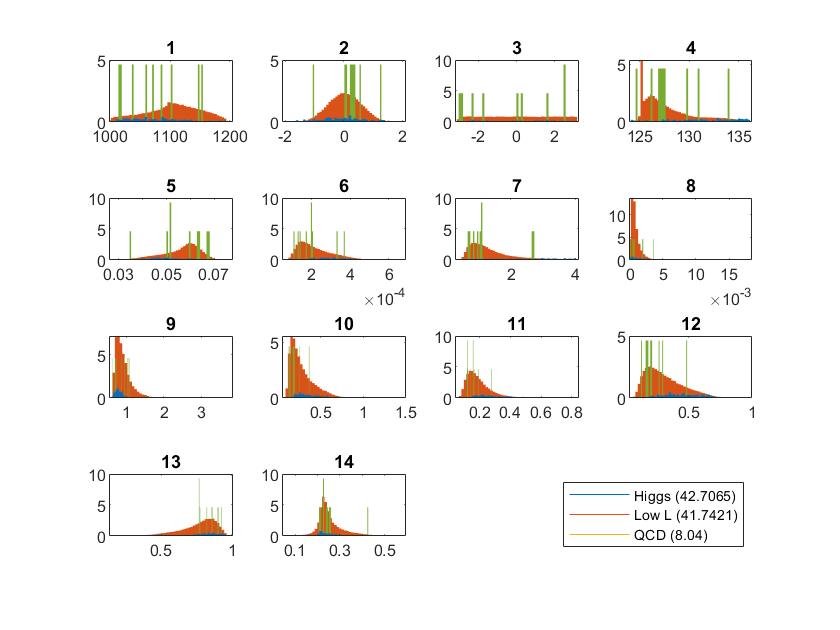

% plotting
close all hidden;
for k = 1:14
    loopsignal = newcutsignal(k,:);
    loopbg = newcutbg(k,:);
    loophighvalues = newcuthighvalues(k,:);
    subplot(4,4,k);
    h = histogram(loopsignal,50,"Normalization","pdf",'HandleVisibility','off');
    set(h,'Visible','off');
    h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
    hold on;
    h2 = histogram(loopbg,50,"Normalization","pdf",'HandleVisibility','off');
    set(h2,'Visible','off');
    h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;
    h3 = histogram(loophighvalues,50,"Normalization","pdf",'HandleVisibility','off');
    set(h3,'Visible','off');
    h3.BinCounts = h3.BinCounts/sum(h3.BinCounts) * nhighl;
    b = bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#D95319');    
    b3 = bar(h3.BinEdges(2:end),h3.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#77AC30');
    
    b2 = bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1,"FaceColor",'#0072BD');

    title("" + k);
    hold off;
end
subplot(4,4,16);
plot(0,0,  0,0,  0,0,  0,0);
axis off;
legend("Higgs (" + nhiggs + ")","Low L (" + nhighl + ")","QCD (" + nqcd + ")");

Again, most of the background has been cut from the low luminosity data. There were fewer data points in the low luminosity data to begin with, so we don't see a smooth distribution. For many of the features you can still see that it is densest at the peaks peaks of the remaining Higgs sample. There is something odd about the distribution of the mass, which is not clustered right at 125 MeV like expected but is rather out at 127 MeV.

nhiggs/sqrt(nqcd)

ans = 15.0614

nhiggs/sqrt(abs(nhighl-nhiggs)) % should not be getting higher

ans = 43.4872

(nhighl-nqcd)/sqrt(abs(nhighl-nhiggs)) % 

ans = 34.3182

(nhighl-nqcd)/sqrt(nqcd) % this got higher last-time, now it is lower

ans = 11.8858

Observed significance should be less than 5 sigma.

## Problem 3